# Homework 7 Lyapunov's method

The given non-linear differential equation


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } \\
\dot{x_3 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\frac{3x_1 +x_3 }{x_2 +1}\\
-\frac{x_2 +2x_3 }{x_2 +3}\\
x_1 
\end{array}\right\rbrack$$


## part (a) use Lyapunov's indirect method

clearvars, clc;
syms x1 x2 x3
RHS = [-(3*x1+x3)/(x2+1);
       -(x2+2*x3)/(x2+3);
       x1]

$$RHS = \left(\begin{array}{c} -\frac{3\,x_{1}+x_{3}}{x_{2}+1}\\ -\frac{x_{2}+2\,x_{3}}{x_{2}+3}\\ x_{1} \end{array}\right)$$


xdot = RHS;
x = [x1; x2; x3];
J = jacobian(RHS, x);

A = subs(J, {x1, x2, x3}, {0, 0, 0});

eigenvalues = eig(A);
ev = double(eigenvalues)

ev =    -0.3333
   -2.6180
   -0.3820


real_parts = real(ev)

real_parts =    -0.3333
   -2.6180
   -0.3820



if all(real_parts < 0)
    disp('All real parts < 0，system is asymptotically stable at equilibrium')
else
    disp('exist real parts >= 0')
end

All real parts < 0，system is asymptotically stable at equilibrium


## part (b) initial response 

here

f = @(t, x) [-(3*x(1) + x(3)) / (x(2) + 1);
             -(x(2) + 2*x(3)) / (x(2) + 3);
             x(1)]

f = function_handle with value:
    @(t,x)[-(3*x(1)+x(3))/(x(2)+1);-(x(2)+2*x(3))/(x(2)+3);x(1)]


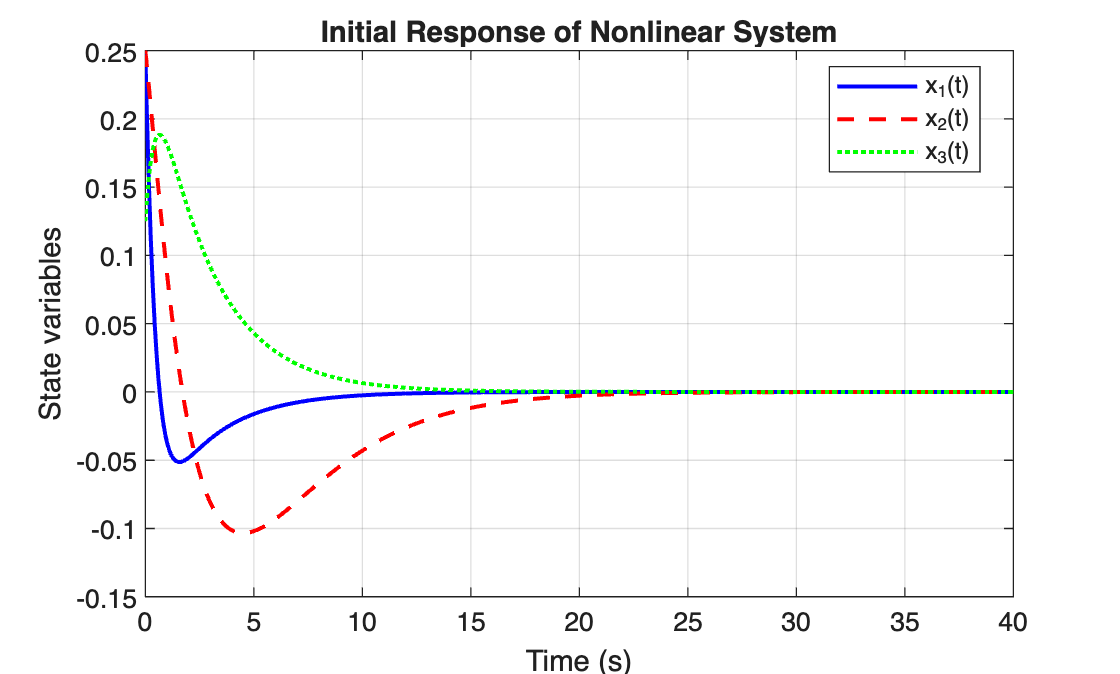


x0   = [0.25; 0.25; 0.125];
tspan = [0, 40];
[t, x] = ode45(f, tspan, x0);

figure;
plot(t, x(:,1), 'b-',  'LineWidth', 1.5); hold on;
plot(t, x(:,2), 'r--', 'LineWidth', 1.5);
plot(t, x(:,3), 'g:',  'LineWidth', 1.5);

xlabel('Time (s)');
ylabel('State variables');
title('Initial Response of Nonlinear System');
legend('x_1(t)', 'x_2(t)', 'x_3(t)', 'Location', 'best');
grid on;

## part (c) find the lyapunov's function and plot time history

The lyapunov's equation is:


$${\mathit{\mathbf{A}}}^T \mathit{\mathbf{P}}+\textrm{PA}=-\mathit{\mathbf{Q}}$$


where $Q=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$. The $\mathit{\mathbf{P}}$ can be found from the lyapunov's quation, The candidate function V is defined as $V\left(\mathit{\mathbf{x}}\right)={\mathit{\mathbf{x}}}^T \textrm{Px}$

Then $\dot{V} \left(x\right)={\dot{x} }^T \textrm{Px}+x^T P\dot{x} ={f\left(x\right)}^T \textrm{Px}+x^T \textrm{Pf}\left(x\right)$

where $\dot{\;\mathit{\mathbf{x}}} =f\left(\mathit{\mathbf{x}}\right)$

Q = eye(3);
%solve A'P + PA = -Q
P = lyap(A', Q)  % MATLAB内置：解 A'P + PA = -Q，注意符号

P =     0.6842   -0.4737    1.5526
   -0.4737    1.5000   -1.5789
    1.5526   -1.5789    5.0263


disp(eig(P));

    0.1849
    0.9123
    6.1132



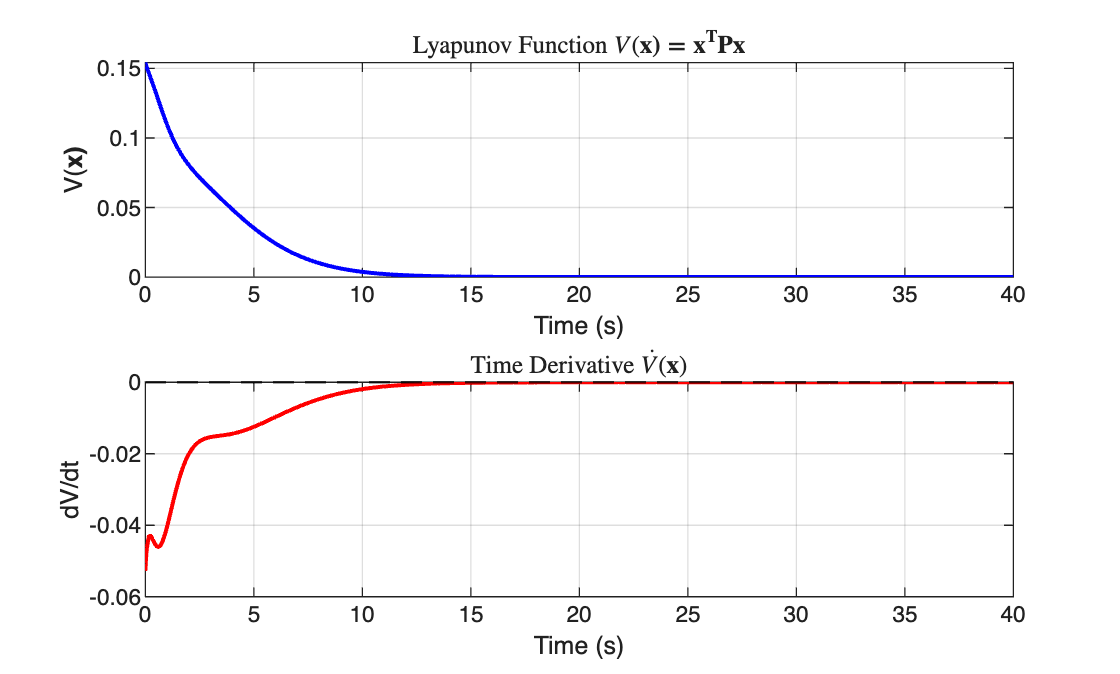


f = @(t, x) [-(3*x(1) + x(3)) / (x(2) + 1);
             -(x(2) + 2*x(3)) / (x(2) + 3);
             x(1)];

x0    = [0.25; 0.25; 0.125];
tspan = [0, 40];
[t, x] = ode45(f, tspan, x0);


% Vdot = f(x)'*P*x + x'*P*f(x) = 2 * x'*P*f(x) 
Vdot = zeros(length(t), 1);
V    = zeros(length(t), 1);

for i = 1:length(t)
    xi = x(i,:)';                          % 当前状态列向量
    fi = f(0, xi);                         % 非线性 f(x)
    V(i)    = xi' * P * xi;                % Lyapunov函数值
    Vdot(i) = fi' * P * xi + xi' * P * fi; % dV/dt
end

figure;
subplot(2,1,1);
plot(t, V, 'b-', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('V(\bf{x})');
title('Lyapunov Function $V(\bf{x}) = \bf{x}^T P \bf{x}$','Interpreter','latex');
grid on;

subplot(2,1,2);
plot(t, Vdot, 'r-', 'LineWidth', 1.5);
yline(0, 'k--', 'LineWidth', 1);
xlabel('Time (s)'); ylabel('dV/dt');
title('Time Derivative $\dot{V}(\mathbf{x})$', 'Interpreter', 'latex');
grid on;

## part (d) expore different initial condition

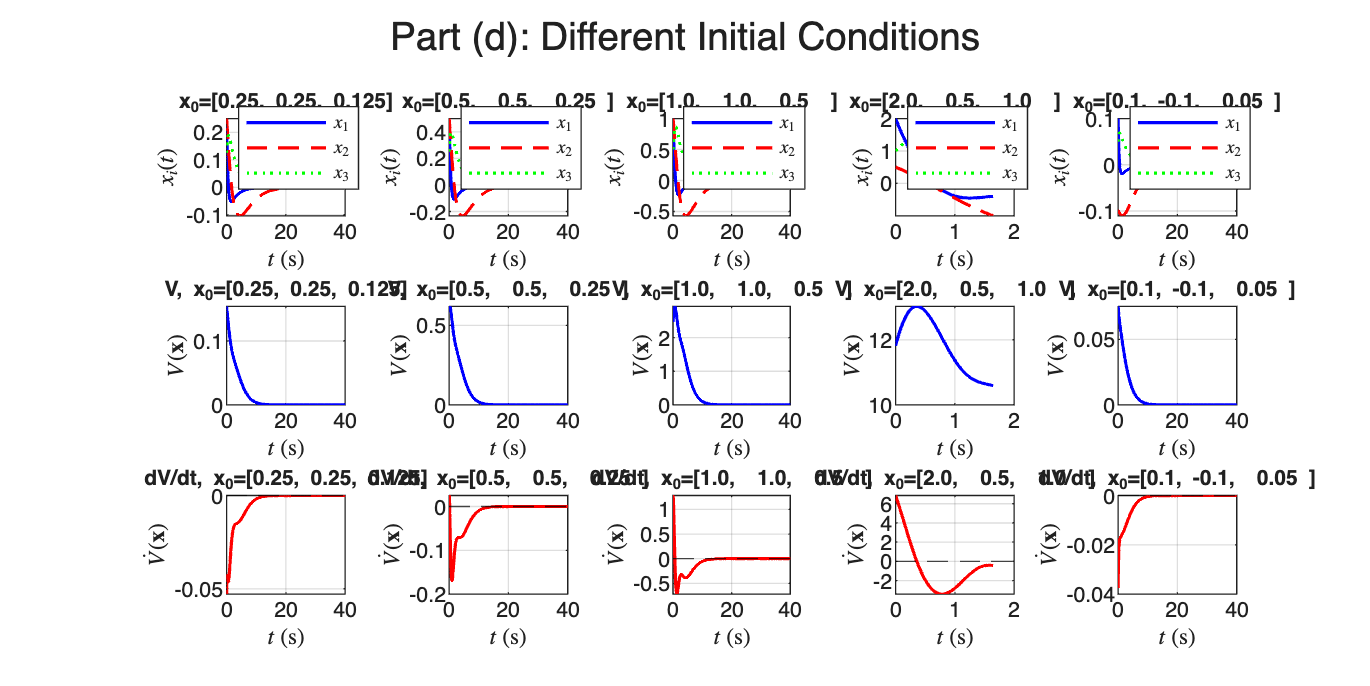

clearvars, clc;

%% 系统与 Lyapunov 函数
f = @(t, x) [-(3*x(1) + x(3)) / (x(2) + 1);
             -(x(2) + 2*x(3)) / (x(2) + 3);
             x(1)];

A = [-3,   0,   -1;
      0,  -1/3, -2/3;
      1,   0,    0];

P    = lyap(A', eye(3));
tspan = [0, 40];

%% 多组初始条件
X0 = [0.25,  0.25,  0.125;   % b问原始条件（近）
      0.5,   0.5,   0.25;    % 稍远
      1.0,   1.0,   0.5;     % 更远
      2.0,   0.5,   1.0;     % 较大初值
      0.1,  -0.1,   0.05];   % 含负值

colors = ['b','r','g','m','c'];
labels = {'x_0=[0.25, 0.25, 0.125]', ...
          'x_0=[0.5,  0.5,  0.25 ]', ...
          'x_0=[1.0,  1.0,  0.5  ]', ...
          'x_0=[2.0,  0.5,  1.0  ]', ...
          'x_0=[0.1, -0.1,  0.05 ]'};

options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9, ...
                 'Events', @singularity_event);

figure('Position', [100 100 1400 700]);

for k = 1:size(X0, 1)
    x0 = X0(k,:)';

    %% 求解（加 try-catch 防止崩溃）
    try
        [t, x] = ode45(f, tspan, x0, options);
    catch
        warning('初始条件 %s 积分失败，跳过', labels{k});
        continue;
    end

    %% 计算 V 和 Vdot
    V    = zeros(length(t), 1);
    Vdot = zeros(length(t), 1);
    for i = 1:length(t)
        xi      = x(i,:)';
        fi      = f(0, xi);
        V(i)    = xi' * P * xi;
        Vdot(i) = fi' * P * xi + xi' * P * fi;
    end

    %% 绘图
    % 状态变量
    subplot(3, size(X0,1), k)
    plot(t, x(:,1),'b-', t, x(:,2),'r--', t, x(:,3),'g:', 'LineWidth',1.2)
    title(labels{k}, 'FontSize', 8)
    xlabel('$t$ (s)',  'Interpreter','latex')
    ylabel('$x_i(t)$', 'Interpreter','latex')
    legend('$x_1$','$x_2$','$x_3$', 'Interpreter','latex', ...
           'Location','best', 'FontSize',7)
    grid on;

    % V
    subplot(3, size(X0,1), k + size(X0,1))
    plot(t, V, 'b-', 'LineWidth', 1.2)
    title(['V, ' labels{k}], 'FontSize', 8)
    xlabel('$t$ (s)',           'Interpreter','latex')
    ylabel('$V(\mathbf{x})$',   'Interpreter','latex')
    grid on;

    % Vdot
    subplot(3, size(X0,1), k + 2*size(X0,1))
    plot(t, Vdot, 'r-', 'LineWidth', 1.2)
    yline(0, 'k--')
    title(['dV/dt, ' labels{k}], 'FontSize', 8)
    xlabel('$t$ (s)',                  'Interpreter','latex')
    ylabel('$\dot{V}(\mathbf{x})$',    'Interpreter','latex')
    grid on;
end

sgtitle('Part (d): Different Initial Conditions')


%% 奇点检测函数
function [value, isterminal, direction] = singularity_event(~, x)
    value      = min(abs(x(2) + 1), abs(x(2) + 3)) - 1e-3;
    isterminal = 1;
    direction  = -1;
end

## Verification: g(x) = f(x) - Ax is higher order

For Lyapunov's indirect method (part a) to be valid, the nonlinear remainder g(x) = f(x) - Ax must be higher order than the linear term, i.e. ||g(x)|| / ||x|| must go to 0 as ||x|| goes to 0. This is checked numerically below along the trajectory from part (b), plotting ||x(t)||, ||g(x(t))|| and the ratio ||g(x(t))|| / ||x(t)||, and also plotting the ratio directly against ||x||.

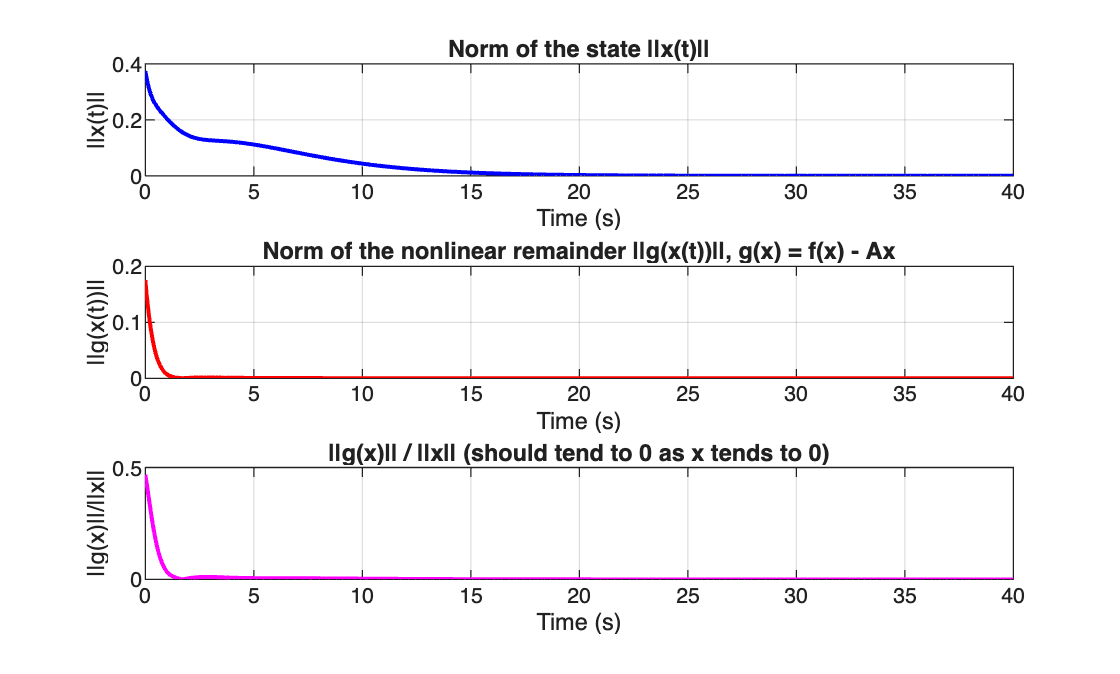

clearvars, clc;

f = @(t, x) [-(3*x(1) + x(3)) / (x(2) + 1);
             -(x(2) + 2*x(3)) / (x(2) + 3);
             x(1)];

A = [-3,    0,    -1;
      0, -1/3,  -2/3;
      1,    0,     0];   % linearization of f at the origin (from part (a))

x0    = [0.25; 0.25; 0.125];
tspan = [0, 40];
[t, x] = ode45(f, tspan, x0);

n = length(t);
normX = zeros(n,1);
normG = zeros(n,1);
ratio = zeros(n,1);

for i = 1:n
    xi = x(i,:)';
    gi = f(0,xi) - A*xi;          % nonlinear remainder g(x) = f(x) - Ax
    normX(i) = norm(xi);
    normG(i) = norm(gi);
    ratio(i) = normG(i)/normX(i);
end

figure;
plot(t, normX, 'b-',  'LineWidth', 1.5); hold on
plot(t, normG, 'r--', 'LineWidth', 1.5);
plot(t, ratio, 'm-.', 'LineWidth', 1.5);
hold off
xlabel('Time (s)'); ylabel('Value');
legend('||x(t)||', '||g(x(t))||', '||g(x(t))||/||x(t)||', 'Location', 'best');
title('||x(t)||, ||g(x(t))|| and ||g(x(t))||/||x(t)|| vs time');
grid on

% Same ratio plotted directly against ||x|| (the variable in the
% theoretical condition lim_{||x||->0} ||g(x)||/||x|| = 0):
[normX_sorted, idx] = sort(normX);
ratio_sorted = ratio(idx);

figure;
loglog(normX_sorted, ratio_sorted, 'k.-')
xlabel('||x||'); ylabel('||g(x)||/||x||');

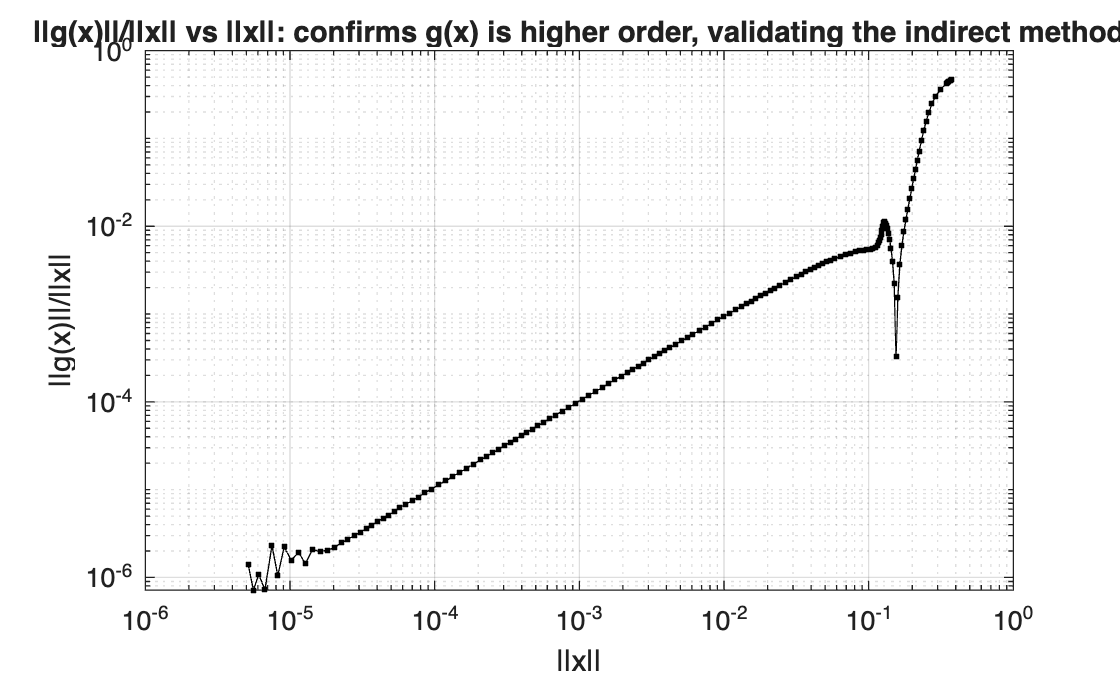

title('||g(x)||/||x|| vs ||x||: confirms g(x) is higher order, validating the indirect method');
grid on